## HiC Binning from 1kb Resolution matrix to resolution of choice

This first section of the script takes 1kb HiC matrix and bins each 1kb by the appropriate number to create a HiC map at equal resolutin to what we expect for our genomic imaging data. 

IF you already have the HiC map matrix as a CSV properly binned. Skip this section and the next (aka go to section 3) and start from there

% === Step 1: Load 1kb-resolution Hi-C matrix ===
%filename = '/Users/home/Desktop/HiC/BCL11a/K562_New/K562_BCL11a_1kb_hic_data_SCALE.csv'; %BCL11a K562
%filename ='/Users/home/Desktop/HiC/BCL11a/IMR_90New/IMR90_Chr2_1kb_hic_data_SCALE.csv'; BCL11a IMR-90
filename = '/Users/home/Desktop/HiC/EGFR/New/Diffed/10kb/EGFR_HL60_10kb_hic_data_SCALE.csv';  % Update with your path
folderPath = '/Users/home/Desktop/HiC/EGFR/New/Diffed/10kb';
rawData = readmatrix(filename);

numColors = 256;
WhiteRed = wrcmap(numColors);
lightGray = [0.9 0.9 0.9];

% === Step 2: Remove coordinate labels ===
hic_1kb = rawData(2:end, 1:end);  % Remove row 1 (assumed labels)

% === Step 3: Trim matrix to square divisible by bin size ===
min_dim = min(size(hic_1kb));
bin_size = 2; % Bin size in kb → 200kb
trim_dim = min_dim - mod(min_dim, bin_size);
hic_trimmed = hic_1kb(1:trim_dim, 1:trim_dim);

% === Step 4: Bin matrix to 200kb resolution ===
new_dim = trim_dim / bin_size;
hic_new = zeros(new_dim);

for i = 1:new_dim
    for j = 1:new_dim
        block = hic_trimmed((i-1)*bin_size+1:i*bin_size, (j-1)*bin_size+1:j*bin_size);
        hic_new(i,j) = mean(block(:), 'omitnan');
    end
end

% === Step 5: Create genomic labels ===
% Define genomic start and bin step (in base pairs)
%start_bp = 59553365; %start for BCL11a
start_bp = 54100000;  % Start coordinate for EGFR
step_bp = bin_size * 1000;  
num_bins = size(hic_new, 1);

% Compute bin **midpoints** for labeling (center-to-center)
bin_start_bp = start_bp : step_bp : start_bp + step_bp * (num_bins - 1);
bin_mid_bp = bin_start_bp + step_bp / 2;

% Convert to Mb and round
labels_mb = round(bin_mid_bp / 1e6, 3);  % Use 3 decimal places to avoid duplicates

% === Step 6: Plot heatmap ===
disHmapColorLim = [0, 10];
figure();

h = heatmap(labels_mb, labels_mb, hic_new, ...
    'Colormap', WhiteRed, ...
    'ColorMethod', 'none', ...
    'ColorLimits', disHmapColorLim, ...
    'GridVisible', 'off', ...
    'CellLabelColor', 'none', ...
    'FontSize', 16, ...
    'MissingDataColor', lightGray);

% Completely remove tick labels from both axes
h.XDisplayLabels = repmat("", 1, size(hic_new, 2)); %to remove the ticks
h.YDisplayLabels = repmat("", size(hic_new, 1), 1); %to remove the ticks

% Keep axis labels and title
xlabel('Genomic Position (Mb)');
ylabel('Genomic Position (Mb)');
title('EGFR Hi-C Heatmap (from 10kb to 20kb Resolution)');

drawnow;

% === Step 7: Save 200kb matrix ===
csvwrite(fullfile(folderPath, 'EGFR_10kb_HiC_20kb_FULL.csv'), hic_new);

## Prints HiC Matrix only at desired resolution

% === Step 8: Export figure ===
print(gcf, fullfile(folderPath, 'EGFR_10kb_HiC_20kb_FULL.pdf'), '-dpdf', '-r300', '-bestfit');
saveas(gcf, fullfile(folderPath, 'EGFR_10kb_HiC_20kb_FULL.png'));

## Section 3: Use this to define variables that you skipped in section 1 and 2

Only run this section if you skipped sections 1 and 2 since you already have the csv

% --- Define existing Hi-C matrix and resolution -------------
filename = 'K:\Experiments\Jessica\HiC\July2025_N54\EGFRfrom_1kb_HiC_100kb_FULL.csv';  % Update with your path
folderPath = 'K:\Experiments\Jessica\HiC\July2025_N54';  %Save Path
hic_1kb = readmatrix(filename);
bin_size    = 10;                       % <-- EDIT HERE: 2 × 10kb = 20kb final bins
start_bp    = 54100000;               % <-- EDIT HERE: genomic start coordinate in bp

% --- Set color and appearance settings ----------------------
numColors   = 256;
WhiteRed    = wrcmap(numColors);       % diverging colormap for Hi-C
WhiteRedUD  = flipud(WhiteRed);         % upside-down for distance map
lightGray   = [0.9 0.9 0.9];            % color for missing data (NaNs)

% --- Trim matrix to a square divisible by bin_size ---------
min_dim     = min(size(hic_1kb));
trim_dim    = min_dim - mod(min_dim, bin_size);
hic_trimmed = hic_1kb(1:trim_dim, 1:trim_dim);

hic_new     = readmatrix(filename);

% --- Create genomic labels in Mb ----------------------------
step_bp     = bin_size * 1000;               % step size in bp
num_bins    = size(hic_new, 1);
bin_start_bp = start_bp : step_bp : start_bp + step_bp * (num_bins - 1);
bin_mid_bp   = bin_start_bp + step_bp / 2;
end_bp = start_bp + step_bp;
bin_end_bp = end_bp : step_bp : end_bp + step_bp * (num_bins - 1);
labels_mb    = round(bin_end_bp / 1e6, 3);   % in Mb, rounded to 3 decimal places

## Combines HiC Matrix and Center-to-Center Distance Matrix on same figure for side by side comparison

This section creates a side by side direct comparison of the HiC Matrix and the Center-to-Center Distance Matrix

Key Note: this section is the STABLE version of the comparison, this requires MANUAL manipulation of the color limits via the first two lines of code. If you're looking for something more dynamic, skip this section of code, and the following and go to the next big section

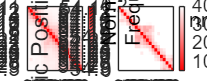

disHmapColorLim = [0, .20];
distColorLim = [50, 400];  % Adjust as needed

fig = figure('Name', 'EGFR 20kb 3D Distance June 2025', 'NumberTitle', 'off', 'Position', [100, 100, 1800, 700]);

% Subplot 1: Hi-C heatmap
subplot(1, 2, 1);
h1 = heatmap(labels_mb, labels_mb, hic_new, ...
    'Colormap', WhiteRed, ...
    'ColorMethod', 'none', ...
    'ColorLimits', disHmapColorLim, ...
    'GridVisible', 'off', ...
    'CellLabelColor', 'none', ...
    'FontSize', 16, ...
    'MissingDataColor', lightGray);
title(h1, 'Hi-C Heatmap');
xlabel(h1, 'Genomic Position (Mb)');
ylabel(h1, 'Genomic Position (Mb)');

% Get current axes and position info
ax = gca;
fig = gcf;

% Add a manual label near the color scale (right side of heatmap)
annotation(fig, 'textbox', [0.47, 0.35, 0.5, 0.05], ...
    'String', 'Normalized Frequency', ...
    'EdgeColor', 'none', ...
    'FontSize', 16, ...
    'HorizontalAlignment', 'left', ...
    'Rotation', 90);

% Subplot 2: Center-to-center distance heatmap
subplot(1, 2, 2);
h2 = heatmap(labels_mb, labels_mb, CentM_NotNorm, ...
    'Colormap', WhiteRedUD, ...
    'ColorMethod', 'none', ...
    'ColorLimits', distColorLim, ...
    'GridVisible', 'off', ...
    'CellLabelColor', 'none', ...
    'FontSize', 16, ...
    'MissingDataColor', lightGray);
title(h2, 'Center-to-Center Distance');
xlabel(h2, 'Genomic Position (Mb)');
ylabel(h2, 'Genomic Position (Mb)');

% Get current axes and position info
ax = gca;
fig = gcf;

% Add a manual label near the color scale (right side of heatmap)
annotation(fig, 'textbox', [.88, 0.9, 0.5, 0.05], ...
    'String', 'nm', ...
    'EdgeColor', 'none', ...
    'FontSize', 16, ...
    'HorizontalAlignment', 'left', ...
    'Rotation', 0);

## Save the manually adjust comparison graphs only

% === Save the figure ===
saveas(fig, fullfile(folderPath, 'EGFR_20kb_from1kb_HiC_vs_C2C_Subplot.png'));
print(fig, fullfile(folderPath, 'EGFR_20kb_from1kb_HiC_vs_C2C_Subplot.pdf'), '-dpdf', '-r300', '-bestfit');

## This is the function for the DYANMIC comparison of HiC vs Imaging data

Key note about this section: This section doesn't output anything, it just sets the function needed for the dynamic printing of the comparison. DO NOT SKIP THIS SECTION if you are wanting to print the dynamic comparison of the data. 

function interactiveHiCViewer(hic_new, CentM_NotNorm, labels_mb, WhiteRed, WhiteRedUD)
    fig = figure('Name', 'EGFR 20kb 3D Distance June 2025', ...
        'NumberTitle', 'off', 'Position', [100, 100, 1800, 1000]);

    % === Subplot 1: Hi-C Heatmap ===
    subplot(1, 2, 1);
    h1 = heatmap(labels_mb, labels_mb, hic_new, ...
        'Colormap', WhiteRed, ...
        'ColorLimits', [0, 10], ...
        'ColorMethod', 'none', ...
        'MissingDataColor', [0.9 0.9 0.9], ...
        'GridVisible', 'off', ...
        'CellLabelColor', 'none');
    xlabel(h1, 'Genomic Position (Mb)');
    ylabel(h1, 'Genomic Position (Mb)');
    title(h1, 'Hi-C Heatmap');

    % Add colorbar label for Hi-C (single line, moved slightly right)
    annotation(fig, 'textbox', [0.485, 0.45, 0.03, 0.1], 'String', 'Normalized Frequency', ...
        'EdgeColor', 'none', 'FontSize', 12, 'Rotation', 90, 'HorizontalAlignment', 'center');

    % === Subplot 2: Distance Heatmap ===
    subplot(1, 2, 2);
    h2 = heatmap(labels_mb, labels_mb, CentM_NotNorm, ...
        'Colormap', WhiteRedUD, ...
        'ColorLimits', [50, 400], ...
        'ColorMethod', 'none', ...
        'MissingDataColor', [0.9 0.9 0.9], ...
        'GridVisible', 'off', ...
        'CellLabelColor', 'none');
    xlabel(h2, 'Genomic Position (Mb)');
    ylabel(h2, 'Genomic Position (Mb)');
    title(h2, 'Center-to-Center Distance');

    % Add colorbar label for Distance (unchanged)
    annotation(fig, 'textbox', [0.925, 0.5, 0.03, 0.1], 'String', 'nm', ...
        'EdgeColor', 'none', 'FontSize', 12, 'Rotation', 90, 'HorizontalAlignment', 'center');

    % === Sliders ===
    uicontrol(fig, 'Style', 'slider', 'Min', 0, 'Max', 1, 'Value', 0, ...
        'Position', [250, 20, 200, 20], ...
        'Callback', @(src, ~) updateColor(h1, src.Value, h1.ColorLimits(2)));

    uicontrol(fig, 'Style', 'slider', 'Min', 0.01, 'Max', 1, 'Value', 0.2, ...
        'Position', [470, 20, 200, 20], ...
        'Callback', @(src, ~) updateColor(h1, h1.ColorLimits(1), src.Value));

    uicontrol(fig, 'Style', 'slider', 'Min', 0, 'Max', 1000, 'Value', 50, ...
        'Position', [740, 20, 200, 20], ...
        'Callback', @(src, ~) updateColor(h2, src.Value, h2.ColorLimits(2)));

    uicontrol(fig, 'Style', 'slider', 'Min', 0, 'Max', 1000, 'Value', 400, ...
        'Position', [960, 20, 200, 20], ...
        'Callback', @(src, ~) updateColor(h2, h2.ColorLimits(1), src.Value));

    % === Toggle Labels Checkbox ===
    showLabelsCheckbox = uicontrol(fig, 'Style', 'checkbox', ...
        'String', 'Show Axis Labels', 'Value', 1, 'FontSize', 11, ...
        'Position', [1180, 20, 150, 25], ...
        'Callback', @(src, ~) toggleAxisLabels(h1, h2, src.Value));

    % === Save Buttons ===
    uicontrol(fig, 'Style', 'pushbutton', 'String', 'Save Figure (.png)', ...
        'Position', [1340, 20, 150, 30], 'FontSize', 12, ...
        'Callback', @(src, ~) saveFigure('png'));

    uicontrol(fig, 'Style', 'pushbutton', 'String', 'Save Figure (.pdf)', ...
        'Position', [1500, 20, 150, 30], 'FontSize', 12, ...
        'Callback', @(src, ~) saveFigure('pdf'));

    % === Color Update Helper ===
    function updateColor(hMap, minVal, maxVal)
        if minVal < maxVal
            hMap.ColorLimits = [minVal, maxVal];
        end
    end

    % === Toggle Axis Labels Helper ===
    function toggleAxisLabels(hmap1, hmap2, on)
        if on
            hmap1.XDisplayLabels = string(labels_mb);
            hmap1.YDisplayLabels = string(labels_mb);
            hmap2.XDisplayLabels = string(labels_mb);
            hmap2.YDisplayLabels = string(labels_mb);
        else
            hmap1.XDisplayLabels = repmat("", 1, size(hic_new, 1));
            hmap1.YDisplayLabels = repmat("", size(hic_new, 1), 1);
            hmap2.XDisplayLabels = repmat("", 1, size(hic_new, 1));
            hmap2.YDisplayLabels = repmat("", size(hic_new, 1), 1);
        end
    end

    % === Save Figure Helper ===
    function saveFigure(ext)
        [file, path] = uiputfile(['*.', ext], ['Save figure as ', upper(ext)]);
        if isequal(file, 0), return; end
        filename = fullfile(path, file);

        % Export Figure (Hidden)
        f = figure('Visible', 'off', 'Position', [100, 100, 1800, 1000]);

        subplot(1, 2, 1);
        exportH1 = heatmap(labels_mb, labels_mb, hic_new, ...
            'Colormap', WhiteRed, ...
            'ColorLimits', h1.ColorLimits, ...
            'ColorMethod', 'none', ...
            'MissingDataColor', [0.9 0.9 0.9], ...
            'GridVisible', 'off', 'CellLabelColor', 'none');
        xlabel(exportH1, 'Genomic Position (Mb)');
        ylabel(exportH1, 'Genomic Position (Mb)');
        title(exportH1, 'Hi-C Heatmap');

        subplot(1, 2, 2);
        exportH2 = heatmap(labels_mb, labels_mb, CentM_NotNorm, ...
            'Colormap', WhiteRedUD, ...
            'ColorLimits', h2.ColorLimits, ...
            'ColorMethod', 'none', ...
            'MissingDataColor', [0.9 0.9 0.9], ...
            'GridVisible', 'off', 'CellLabelColor', 'none');
        xlabel(exportH2, 'Genomic Position (Mb)');
        ylabel(exportH2, 'Genomic Position (Mb)');
        title(exportH2, 'Center-to-Center Distance');

        if showLabelsCheckbox.Value == 0
            exportH1.XDisplayLabels = repmat("", 1, size(hic_new, 1));
            exportH1.YDisplayLabels = repmat("", size(hic_new, 1), 1);
            exportH2.XDisplayLabels = repmat("", 1, size(hic_new, 1));
            exportH2.YDisplayLabels = repmat("", size(hic_new, 1), 1);
        end

        % Add colorbar labels to export figure (updated position)
        annotation(f, 'textbox', [0.485, 0.45, 0.03, 0.1], 'String', 'Normalized Frequency', ...
            'EdgeColor', 'none', 'FontSize', 12, 'Rotation', 90, 'HorizontalAlignment', 'center');
        annotation(f, 'textbox', [0.925, 0.5, 0.03, 0.1], 'String', 'nm', ...
            'EdgeColor', 'none', 'FontSize', 12, 'Rotation', 90, 'HorizontalAlignment', 'center');

        switch ext
            case 'png'
                saveas(f, filename);
            case 'pdf'
                print(f, filename, '-dpdf', '-r300', '-bestfit');
        end
        close(f);
        disp(['Figure saved to ', filename]);
    end
end

## Combines HiC Matrix and Center-to-Center Distance Matrix on same figure for side by side comparison - DYNAMIC Version

Key note: This is the dynamic printing of the comparison. Yes, only one line of code ;) 

FYI- PDF printing is not optimized at this point in time June 2025, print to .png for the best formatted

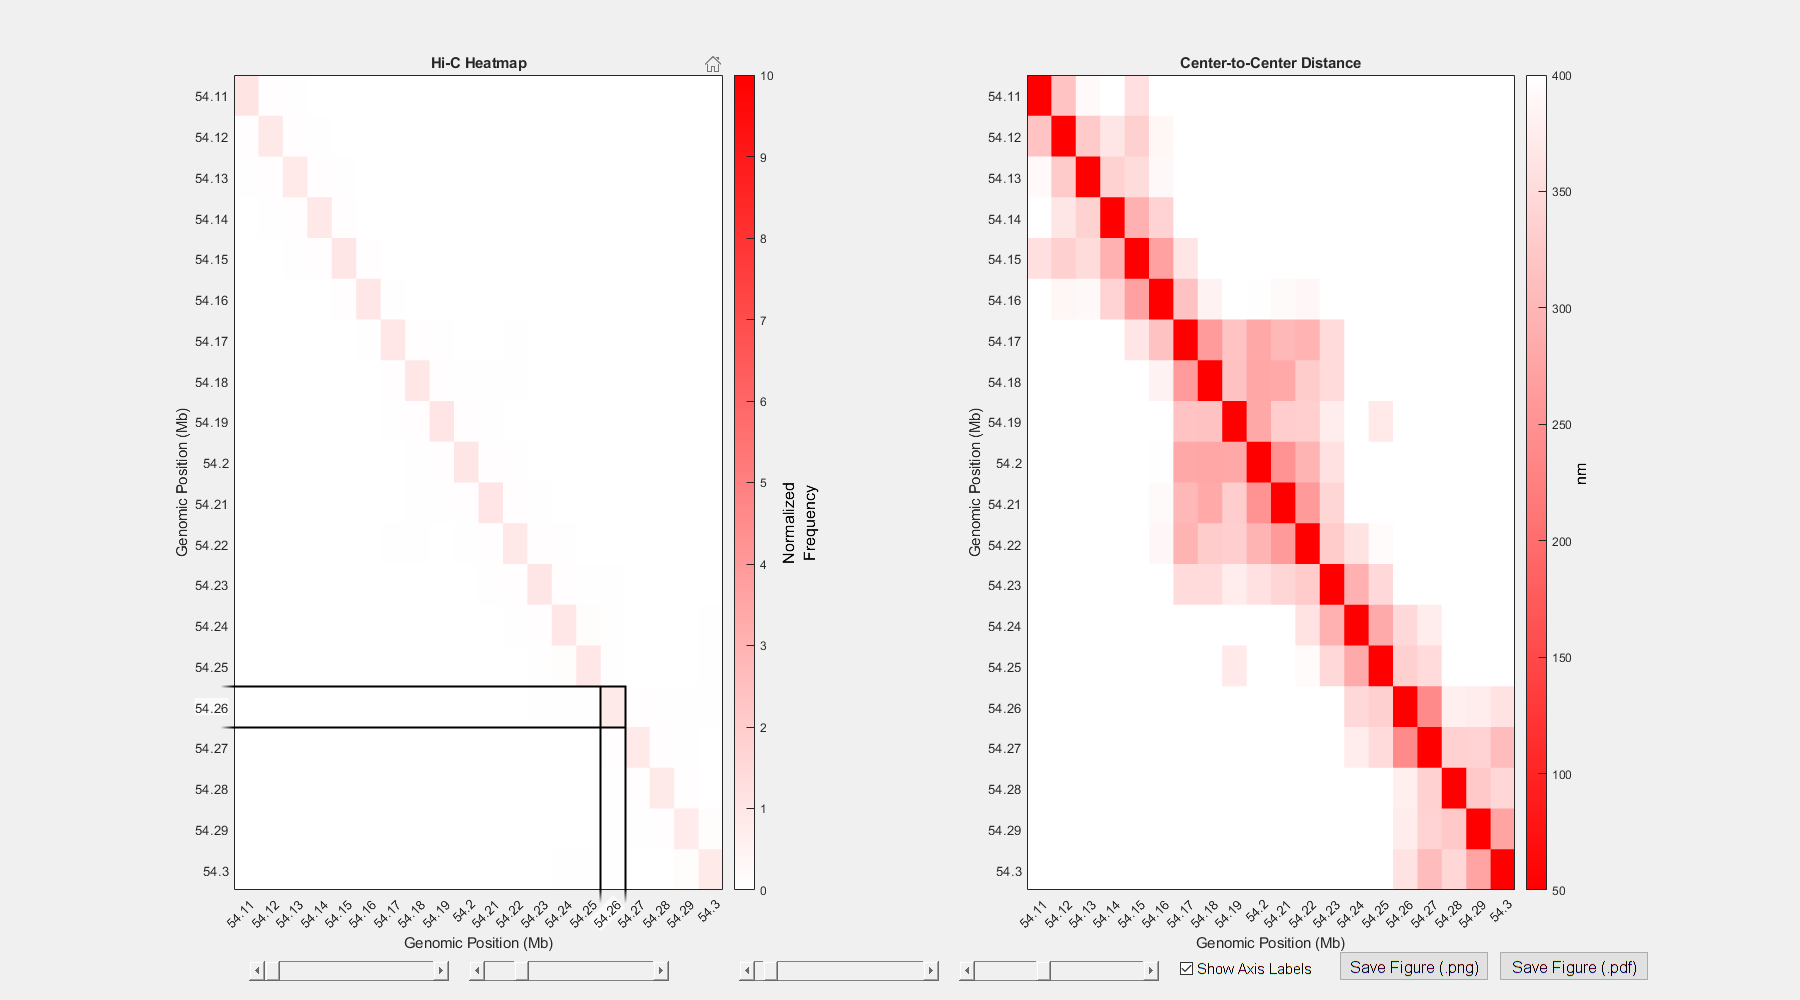

interactiveHiCViewer(hic_new, CentM_NotNorm, labels_mb, WhiteRed, WhiteRedUD);

## Save MatLab workspace 

This will allow you to save the matlab space with all the variables 

% === Save entire workspace to .mat file ===
matSavePath = fullfile(folderPath, 'EGFR_June2025_20kb_from1kb_HiC_C2C_FullWorkspace.mat');
save(matSavePath);
fprintf('✅ Full workspace saved to:\n%s\n', matSavePath);